%inputs
clearvars
format shortG
xmin = -7;
xmax = 7;
ymin = -7;
ymax = 7;
zmin = 0;
zmax = 7;
xint = 0.2;
yint = 0.2;
zint = 0.2;
xtotal = ((xmax-xmin)/xint + 1);
ytotal = ((ymax-ymin)/yint + 1);
ztotal = ((zmax-zmin)/zint + 1);
datasize = xtotal*ytotal*ztotal;

diameter = 4.98; %mm
height = 1.97; %mm
Br_max = 12100*0.1; %mT
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2

%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);

import = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM03162023\PIM03202023_DataAvg.txt');
location = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\m7t7_m7to7_0to1p5_0p2Increment.txt');
dataavg = import.data(:,2:7);
dataavg= sortrows(dataavg, [3 2 1])

dataavg =            -7           -7            0     0.068558      0.41832      -1.9305
         -6.8           -7            0     0.068072       0.4174      -1.9321
         -6.6           -7            0     0.065018      0.41686      -1.9326
         -6.4           -7            0     0.059892      0.41607      -1.9343
         -6.2           -7            0     0.054047      0.41568      -1.9349
           -6           -7            0     0.047221       0.4144      -1.9355
         -5.8           -7            0     0.040901      0.41344      -1.9369
         -5.6           -7            0     0.032801       0.4121      -1.9379
         -5.4           -7            0     0.022901      0.41126      -1.9378
         -5.2           -7            0     0.012017      0.41003      -1.9389


%dataavg = dataavg + [0, 0, 15, 0, 0, 0]
% H_0 = repelem([0 0 1], [datasize], [1]);
% R = sqrt(sum(location.^2, 2));
% X = -location;
% B = B_t*(3*dot(H_0, X, 2).*X./R.^5-H_0./R.^3)

size = 500;
loc = location(1:size, :);
B_data = dataavg(1:size, 4:6);
costfun = @(v)costh(v, loc, B_data, B_t, size);
nonlcon = @con;

x0 = [0.1,0.1,0.1];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [0, 0, 0];
ub = [1, 1, 1];
[min, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


min =          0.999999929278654      2.30241049427275e-07      1.19211584932119e-06


fval =           1497129.46577448


%writematrix(dataavg(:,1:3), 'C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\m7t07_m7to7_0to6p2_0p2Increment.txt')
% xfive = find(abs(dataavg(:,1)) < 1.1);
% x5 = dataavg(xfive,:);

z5 =            -1           -1            0     -0.30567     -0.14417      -1.8421
         -0.8           -1            0     -0.31657      -0.1436       -1.837
         -0.6           -1            0     -0.32646     -0.14274      -1.8335
         -0.4           -1            0     -0.33806     -0.14242       -1.828
         -0.2           -1            0     -0.34748     -0.14164      -1.8231
            0           -1            0      -0.3586     -0.14093      -1.8166
          0.2           -1            0     -0.37052     -0.14031      -1.8103
          0.4           -1            0     -0.38364     -0.13937      -1.8026
          0.6           -1            0     -0.39533     -0.13924      -1.7955
          0.8           -1            0     -0.40889     -0.13811      -1.7876


% yfive = find(abs(x5(:,2)) < 1.1);
% y5 = x5(yfive,:);
% zfive = find(abs(y5(:,3)) < 1.1);
% z5 = y5(zfive,:)

options = optimoptions('fmincon','Algorithm','trust-region-reflective', 'MaxFunctionEvaluations',1e20);
options.MaxFunctionEvaluations

% B_data = dataavg(5 ,4:6);

ans =         1e+20


% costfun = @(v)cost(v, B_data, B_t);
% nonlcon = @con;
% 
% x0 = [0,0,5,0,0,0];
% A = [];
% b = [];
% Aeq = [];
% beq = [];
% lb = [-10, -10, 0, 0, 0, 0];
% ub = [10, 10, 30, 1, 1, 1];
% [min fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)

% ind = 2500;
% d_data = z5(:,4:6);
% loc = z5(:, 1:3);
% datasize = length(d_data(:,1));
% dcostfun = @(v)costd(v, loc, d_data, B_t, datasize);
% nonlcon = @con;
%         
% x0 = [0,0,1,0,0,0];
% A = [];
% b = [];
% Aeq = [];
% beq = [];
% lb = [-10,-10,-30,0,0,0];
% ub = [10,10,0,1,0.1,1];
% [min1, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)

04/25/2023

Try to fit using points closest to center of magnet.

Change optimization minimization algorithms

Maybe solve for angle from contour data and fit to that.

Get account set up for MSI (supercomputing)

% sqrt(sum(min1(4:6).^2,2))
% min1(4)^2;
% min1(5)^2;


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


min1 =    3.7954e-05   2.6825e-05           -1      0.21936     0.098404      0.21936


fval =    2.7567e+09


% min1(6)^2;
% % locpred
% % location
% loc = dataavg(:,1:3)
% datasize = length(dataavg);
% H_02 = repelem(min1(4:6), datasize, 1);
% R2 = sqrt(sum(loc.^2, 2));

ans =       0.32546


% X2 = min1(1:3)-loc;
% B2 = B_t*(3*dot(H_02, X2, 2).*X2./R2.^5-H_02./R2.^3)
% dataavg
% dataavg(:, 4:6)
% dataavg(:, 4:6) - B2

format longG

loc =            -7           -7            0
         -6.8           -7            0
         -6.6           -7            0
         -6.4           -7            0
         -6.2           -7            0
           -6           -7            0
         -5.8           -7            0
         -5.6           -7            0
         -5.4           -7            0
         -5.2           -7            0


zzero = find(abs(dataavg(:,3)-0) < 0.1);

zzeromat = dataavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
sqrt(length(zeroB))

B2 =       0.80086       1.2615      -1.0692
      0.79786       1.3278      -1.1176
      0.79154       1.3965       -1.168
      0.78151       1.4676      -1.2204
      0.76734       1.5408      -1.2749
       0.7486        1.616      -1.3314
      0.72481       1.6929      -1.3898
       0.6955        1.771      -1.4502
      0.66018       1.8501      -1.5124
      0.61836       1.9295      -1.5763


zeroB = reshape(zeroB, [71 71]);

dataavg =            -7           -7            0     0.068558      0.41832      -1.9305
         -6.8           -7            0     0.068072       0.4174      -1.9321
         -6.6           -7            0     0.065018      0.41686      -1.9326
         -6.4           -7            0     0.059892      0.41607      -1.9343
         -6.2           -7            0     0.054047      0.41568      -1.9349
           -6           -7            0     0.047221       0.4144      -1.9355
         -5.8           -7            0     0.040901      0.41344      -1.9369
         -5.6           -7            0     0.032801       0.4121      -1.9379
         -5.4           -7            0     0.022901      0.41126      -1.9378
         -5.2           -7            0     0.012017      0.41003      -1.9389


zerox = reshape(zzeromat(:,1), [71 71]);

ans =      0.068558      0.41832      -1.9305
     0.068072       0.4174      -1.9321
     0.065018      0.41686      -1.9326
     0.059892      0.41607      -1.9343
     0.054047      0.41568      -1.9349
     0.047221       0.4144      -1.9355
     0.040901      0.41344      -1.9369
     0.032801       0.4121      -1.9379
     0.022901      0.41126      -1.9378
     0.012017      0.41003      -1.9389


zeroy = reshape(zzeromat(:,2), [71 71]);

ans =      -0.73231     -0.84321     -0.86132
     -0.72978     -0.91041     -0.81453
     -0.72652     -0.97967      -0.7646
     -0.72161      -1.0515     -0.71386
      -0.7133      -1.1252     -0.65997
     -0.70138      -1.2016     -0.60416
     -0.68391      -1.2794     -0.54709
      -0.6627      -1.3589     -0.48766
     -0.63728      -1.4388      -0.4254
     -0.60634      -1.5195     -0.36258



contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 0 mm')
xlabel('X (mm)')
ylabel('Y (mm)')

ans =     71


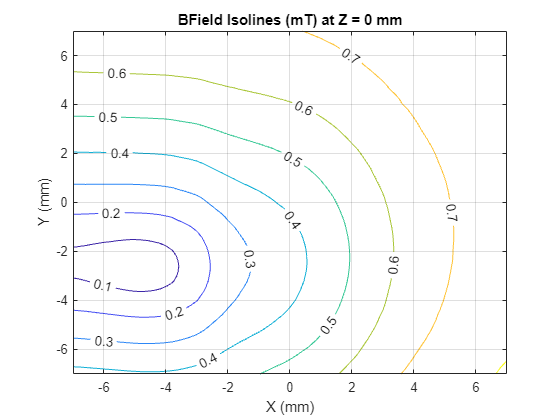

hold off

ztwo = find(abs(dataavg(:,3)-1) < 0.1);

ztwomat = dataavg(ztwo,:);
twoB = sqrt(sum(ztwomat(:,4:5).^2,2));
twoB = reshape(twoB, [71 71]);
twox = reshape(ztwomat(:,1), [71 71]);
twoy = reshape(ztwomat(:,2), [71 71]);

contour(twox, twoy, twoB, 'ShowText', 'on')

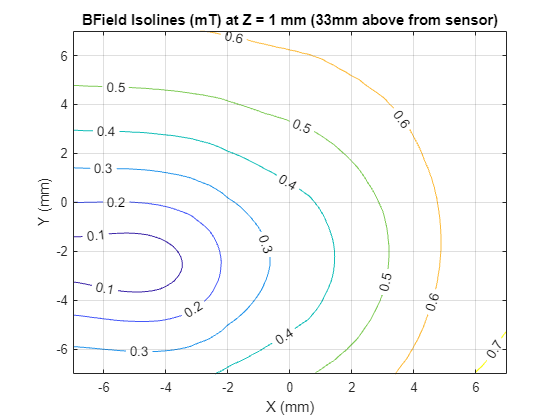

hold on;
grid on;
title('BField Isolines (mT) at Z = 1 mm (33mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off;

zfour = find(abs(dataavg(:,3)-4) < 0.1);

zfourmat = dataavg(zfour,:);
fourB = sqrt(sum(zfourmat(:,4:5).^2,2));
fourB = reshape(fourB, [71 71]);
fourx = reshape(zfourmat(:,1), [71 71]);
foury = reshape(zfourmat(:,2), [71 71]);

contour(fourx, foury, fourB, 'ShowText', 'on')

hold on;
grid on;
title('BField Isolines (mT) at Z = 4 mm (33mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off;

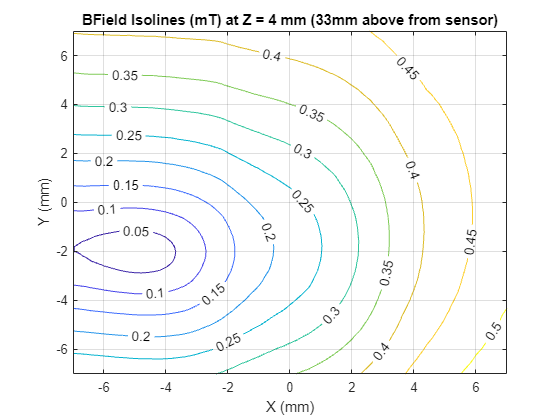

function b = cost(v, B_data, B_t, size)
X1 = [-v(1) -v(2) -v(3)];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 1], size, 1);
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;

end

function d = costd(v, loc, B_data, B_t, size)
X1 = [v(1) v(2) v(3)] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 1], size, 1);
d = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function h = costh(v, loc, B_data, B_t, size)
X1 = -loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], size, 1);
h = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function s = costs(v, loc, B_data, B_t, size)
X1 = [v(1) v(2) v(3)] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 1], size, 1);
s = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end